# Hands-On: C2D with Sampler & Hold - First Experiment

## First Scenario: Discretising  an LTI System with only Real Eigenvalues

Let's consider the continuous-time LTI system


$$\left\{ \begin{array}{lcl}
			\dot{x}(t) &=& \left[ \begin{array}{cc} 
												0 & 1\\0 & -1 
											\end{array} \right] \cdot x(t) + \left[\begin{array}{c} 0 \\ 10  \end{array} \right] \cdot u(t) \\[0.5em] \\
			y(t) &=&\left[ \begin{array}{cc}
									 1 & 0
									\end{array}  \right] \cdot x(t)
			\end{array} \right.$$


What happens, if you choose a few different sampling periods $\Delta_1\,,\; \Delta_2\,, \ldots \Delta_{10}$ such that

 
$$\Delta_i \in \left[ \frac{1}{1000} \,,\; 10 \right] \quad \forall i = 1\,,\;2\,, \ldots 10$$


and then compute the discrete-time description of the considered LTI system?

Write a piece of code, allowing:

-  To select a set of sample periods, as specified above;

-  To compute, for each selected sampling time, the discrete time representation of the given continuous time LTI system;

-  To plot the eigenvalues of the discrete-time description of the given LTI system;

- To compare the free state movement of the continuous time system and the free state movement of each discrete time description, starting from the initial state $x_{0} = \left[ \begin{array}{cc} -2 & +3 \end{array} \right]^{T}$


% write here the code solving the problem 

close all
clear all
clc

A = [0 1; 0 -1];

B = [0 10]';

C = [1 0];

D = 0;

delta = logspace(-3, 1, 10)

delta =     0.0010    0.0028    0.0077    0.0215    0.0599    0.1668    0.4642    1.2915    3.5938   10.0000



sys_c = ss(A, B, C, D);

sys_1= c2d(sys_c, delta(1));
sys_2= c2d(sys_c, delta(2));
sys_3= c2d(sys_c, delta(3));
sys_4= c2d(sys_c, delta(4));
sys_5= c2d(sys_c, delta(5));
sys_6= c2d(sys_c, delta(6));
sys_7= c2d(sys_c, delta(7));
sys_8= c2d(sys_c, delta(8));
sys_9= c2d(sys_c, delta(9));
sys_10= c2d(sys_c, delta(10));

[y_c, tOut_c] = step(sys_c);

[y_d1, tOut_d1] = step(sys_1);
[y_d2, tOut_d2] = step(sys_2);
[y_d3, tOut_d3] = step(sys_3);
[y_d4, tOut_d4] = step(sys_4);
[y_d5, tOut_d5] = step(sys_5);
[y_d6, tOut_d6] = step(sys_6);
[y_d7, tOut_d7] = step(sys_7);
[y_d8, tOut_d8] = step(sys_8);
[y_d9, tOut_d9] = step(sys_9);
[y_d10, tOut_d10] = step(sys_10);

%plot(tOut_c, y_c);
%grid on;

%plot(tOut_d4, y_d4, '-',tOut_d3, y_d3,'.', LineWidth=2);
%grid on;

eig(sys_1.A)

ans =     1.0000
    0.9990


eig(sys_2.A)

ans =     1.0000
    0.9972


eig(sys_3.A)

ans =     1.0000
    0.9923


eig(sys_4.A)

ans =     1.0000
    0.9787


eig(sys_5.A)

ans =     1.0000
    0.9418


eig(sys_6.A)

ans =     1.0000
    0.8464


eig(sys_7.A)

ans =     1.0000
    0.6287


eig(sys_8.A)

ans =     1.0000
    0.2748


eig(sys_9.A)

ans =     1.0000
    0.0275


eig(sys_10.A)

ans =     1.0000
    0.0000


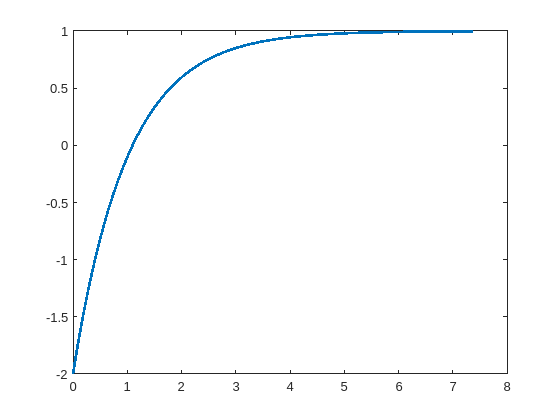

x0 = [-2 3]';

[y_c, t_c] = initial(sys_c, x0);
[y_1, t_1] = initial(sys_1, x0);
[y_2, t_2] = initial(sys_2, x0);
[y_3, t_3] = initial(sys_3, x0);
[y_4, t_4] = initial(sys_4, x0);
[y_5, t_5] = initial(sys_5, x0);
[y_6, t_6] = initial(sys_6, x0);
[y_7, t_7] = initial(sys_7, x0);
[y_8, t_8] = initial(sys_8, x0);
[y_9, t_9] = initial(sys_9, x0);
[y_10, t_10] = initial(sys_10, x0);

plot(t_c, y_c, LineWidth=2);

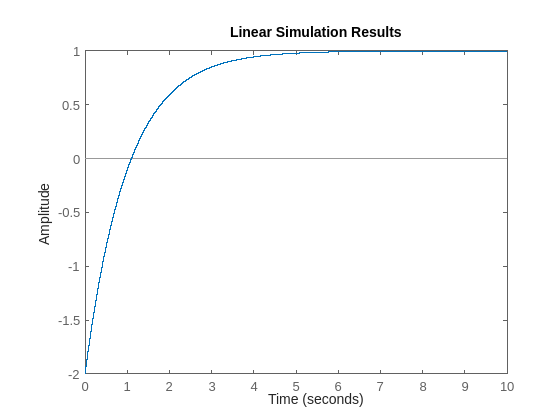

t = 0:delta(1):10;
U = zeros(1, size(t, 2));
lsim(sys_1, U, t, x0);

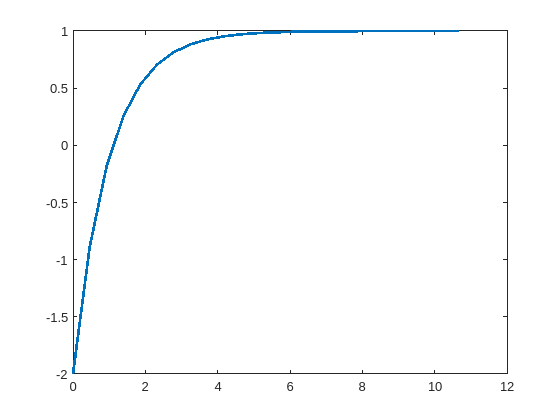

plot(t_7, y_7, '-', LineWidth=2);

- What could be the behavior of the discrete-time description eigenvalues, when increasing or decreasing the sampling frequency $f_s = 1/ \Delta$ ? 

Decreasing the sampling frequency makes the second eigen value converge to zero due to the lack of informatio caused from the low frequency.

- Did you find any difference between the free movement of the state of the original continuous-time system and the discrete-time representations you obtained?

From Delta = 0.1668 the behavior remain pretty the same but with less information on the transitory movement,

- Finally, analysing the results, try to figure out a good choice for $\Omega_{\text{B}}$, or equivalently for $f_{\text{B}}$ , in order to obtain a proficient discrete-time description of the given LTI system.

Using the sixth period (0.1668), which means 6 Hz of Band Width, means the sampling frequency should be around 3 Hz

Now suppose to feed the continuous time system with the input 


$$u(t) = t e^{-4t}\sin \left(2 \pi \bar{f}t - \frac{pi}{6}\right)\cdot 1(t) \quad \bar{f} = 2.0\;\text{[Hz]}$$


and assume to sample also the input signal, beside the state and the output variables.

- Is the previously chosen sampling period still a good choice? Or do you have to select a different value?

- What if $\bar{f} = 200.0 \; \text{[Hz]}$?

- Write a few lines of code, implementing a comparison of the state and output movements, starting from the assigned initial state $x_0$ and the predefined input, for the continuous-time system and the discrete-time representation obtained, discretizing the system equations according to the chosen sampling period.

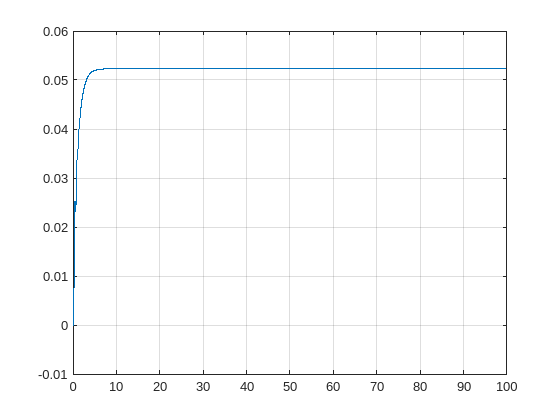


% write here the code solving the problem 
t=0:0.01:100;
f = 2;
u = t.*exp(-4.*t).*sin(2.*pi.*f.*t-pi/6);
[y, t] = lsim(sys_c, u, t);

t1=0:0.1668:100;
u1 = t1.*exp(-4.*t1).*sin(2.*pi.*f.*t1-pi/6);
[y1, t1] = lsim(sys_6, u1, t1);

plot(t, y);
grid on;

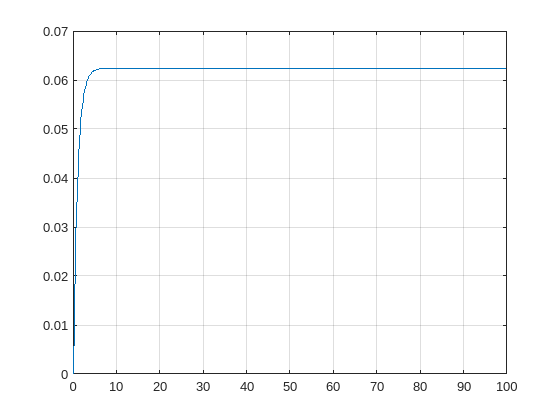

plot(t1, y1);
grid on;

## Second Scenario: Discretising an LTI System with Complex Eigenvalues

Consider now the continuous-time LTI system


$$\left\{ \begin{array}{lcl}
			\dot{x}(t) &=& \left[ \begin{array}{cc} 
												1 & 2\\-2 & 1 
											\end{array} \right] \cdot x(t) + \left[\begin{array}{c} 0 \\ 10  \end{array} \right] \cdot u(t) \\[0.5em] \\
			y(t) &=&\left[ \begin{array}{cc}
									 1 & 0
									\end{array}  \right] \cdot x(t)
			\end{array} \right.$$


and repeat the same computation steps. What is your finding?


% write here the code solving the problem 


Do you find any significant difference by comparing the two cases? 